# Simulation

To be the as realistic as possible in simulation we've downloaded real scans of Italy mountains (area W51570 from INGV [https://tinitaly.pi.ingv.it/Download_Area1_1.html).](https://tinitaly.pi.ingv.it/Download_Area1_1.html).)

From this large area we select the top-right 1/16 square, and from this the bottom left 1/16 square

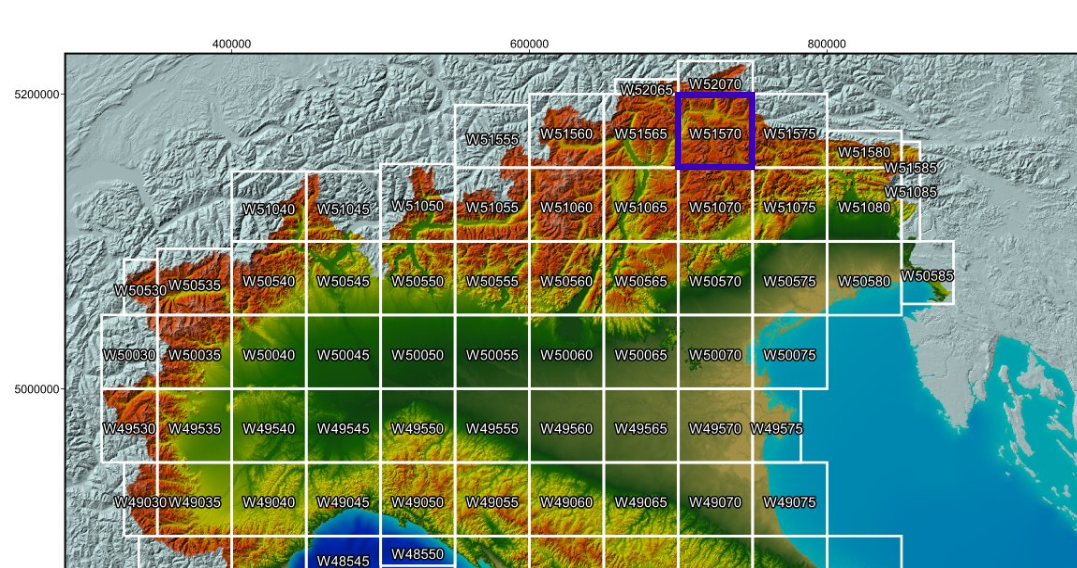

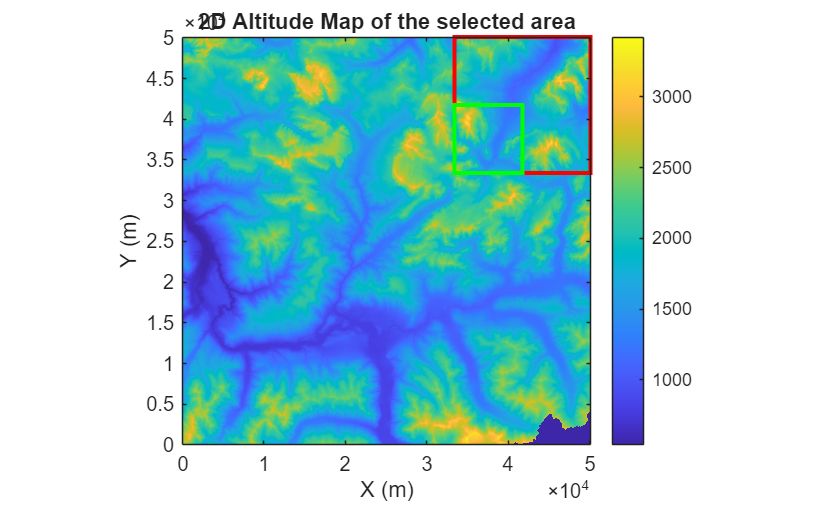

[Z, R] = readgeoraster('map.tif');
Z = double(Z);

x = linspace(R.XWorldLimits(1), R.XWorldLimits(2), size(Z,2)); 
y = linspace(R.YWorldLimits(1), R.YWorldLimits(2), size(Z,1));
x = x - x(1);
y = y - y(1);
[X, Y] = meshgrid(x,y);

figure, clf;
imagesc(x, y, Z)    
set(gca, 'YDir', 'normal')  
xlabel('X (m)')
ylabel('Y (m)')
title('2D Altitude Map of the selected area')
colormap(parula)
colorbar
axis equal tight
hold on

% Dimensions
[nRows, nCols] = size(Z);

% --- First square: top-right 1/16 ---
rowRange1 = round(2*nRows/3) : nRows;
colRange1 = round(2*nCols/3) : nCols;

x1 = x(colRange1(1));
y1 = y(rowRange1(1));
w1 = x(colRange1(end)) - x(colRange1(1));
h1 = y(rowRange1(end)) - y(rowRange1(1));

rectangle('Position', [x1, y1, w1, h1], ...
          'EdgeColor', 'r', 'LineWidth', 2)

% --- Second square: bottom-left of the first ---
subZ = Z(rowRange1, colRange1);
[subRows, subCols] = size(subZ);

rowRange2 = 1 : round(subRows/2);
colRange2 = 1 : round(subCols/2);

% Converti negli indici globali
rowRange2_global = rowRange1(rowRange2);
colRange2_global = colRange1(colRange2);

% Coordinate reali rettangolo 2
x2 = x(colRange2_global(1));
y2 = y(rowRange2_global(1));
w2 = x(colRange2_global(end)) - x(colRange2_global(1));
h2 = y(rowRange2_global(end)) - y(rowRange2_global(1));

rectangle('Position', [x2, y2, w2, h2], ...
          'EdgeColor', 'g', 'LineWidth', 2)

Now from the selected (green) area we choose another area that will be the actual operational environment, the avalanche zone. In the development part it will be a fixed zone, in the testing phase it will be randomly chosen within the selected (green) area.

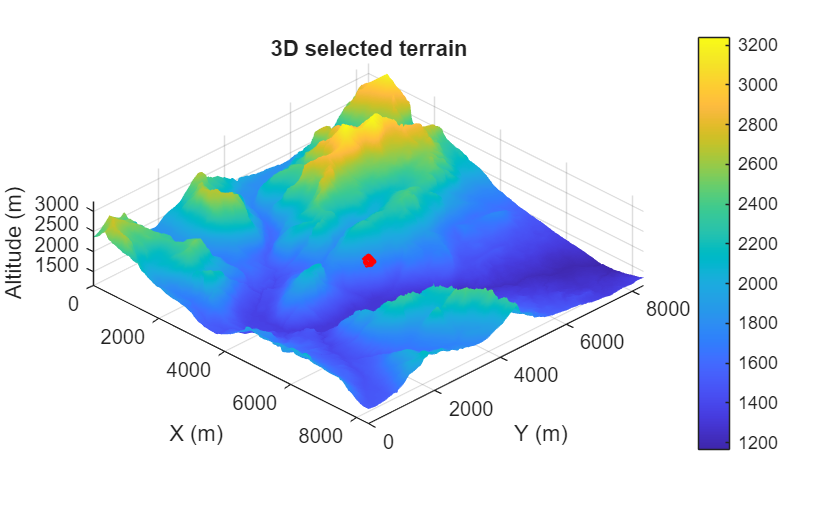

% --- Extract the final square (green one) ---
Z_sel = Z(rowRange2_global, colRange2_global);
X_sel = X(rowRange2_global, colRange2_global);
Y_sel = Y(rowRange2_global, colRange2_global);

X_sel = X_sel - X_sel(1);
Y_sel = Y_sel - Y_sel(1);

% --- 3D plot ---
figure, clf;
surf(X_sel, Y_sel, Z_sel)

shading interp          
colormap(parula)
colorbar

xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('3D selected terrain')

axis equal
view(45,30)
hold on

% --- Workspace dimension [m] ---
L = 150;

% --- Choose a position (eventually random) ---
x0 = (max(X_sel(:)) - L)/2;
y0 = (max(Y_sel(:)) - L)/2;

% square corners
x_sq = [x0 x0+L x0+L x0 x0];
y_sq = [y0 y0 y0+L y0+L y0];

% project on the 3d surface
z_sq = interp2(X_sel, Y_sel, Z_sel, x_sq, y_sq);

% --- Draw the projected square ---
plot3(x_sq, y_sq, z_sq, 'r-', 'LineWidth', 3)

% Trova indici dentro il range 150x150
idx_x = find(x >= x0 & x <= x0 + L);
idx_y = find(y >= y0 & y <= y0 + L);

% Estrai sottosezione
X_ws = X_sel(idx_y, idx_x);
Y_ws = Y_sel(idx_y, idx_x);
Z_ws = Z_sel(idx_y, idx_x);

X_ws = X_ws - X_ws(1);
Y_ws = Y_ws - Y_ws(1);

%define the equivalent function
F = griddedInterpolant(X_ws', Y_ws', Z_ws', 'linear', 'nearest');

m = 1.5;
phi = (1 + sqrt(5)) / 2; 
kp = 10000;
kd = 100;
dt = 0.01;
N = 100;
t0 = 0;
tf = t0 + N*dt;
t = linspace(t0, tf, N);
x_ref = 50 + (25*phi.^(4*t).*cos(2*pi*t))';
y_ref = 50 + (25*phi.^(4*t).*sin(2*pi*t))';
xd_ref = gradient(x_ref, dt);
yd_ref = gradient(y_ref, dt);


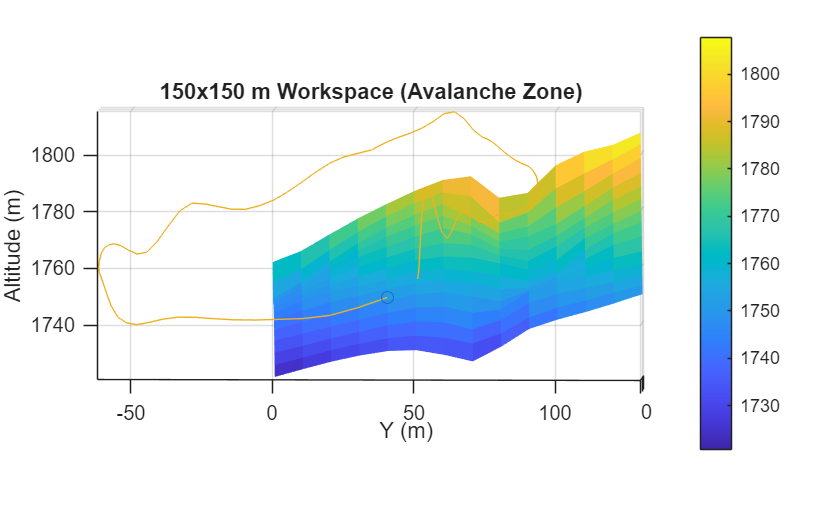

% then we build a simple P controller to control the force correctly:
%first measure
s0 = [x_ref(1), y_ref(1), 1750, xd_ref(1), yd_ref(1), 0];
s_res = zeros(N,6);
s_res(1,:) = s0;
for k = 1:N-1
    % measure
    % ...
    % trajectory calculation
    s_ref = [x_ref(k), y_ref(k), F(s_res(k, 1:2))+20, xd_ref(k), y_ref(k), 0];
    % control
    u = kp*(s_ref(1:3) - s_res(k, 1:3)) + kd*(s_ref(4:6) - s_res(k, 4:6));
    % drone dynamic
    s_res(k+1,:) = DroneForwardDynamicsStep(s_res(k,:), u , m, dt);
end

figure, clf;

surf(X_ws, Y_ws, Z_ws)
hold on
comet3(s_res(:,1), s_res(:,2), s_res(:,3))
shading flat
colormap(parula)
colorbar

xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('150x150 m Workspace (Avalanche Zone)')

axis equal
view(45,30)

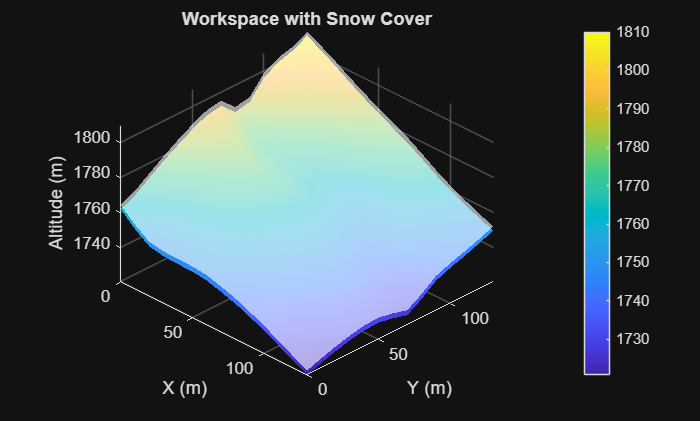

figure, clf;
surf(X_ws, Y_ws, Z_ws)
hold on

shading interp
colormap(parula)
colorbar

xlabel('X (m)')
ylabel('Y (m)')
zlabel('Altitude (m)')
title('Workspace with Snow Cover')

axis equal
view(45,30)

% --- PARAMETRI NEVE ---
H0 = 2;        % spessore medio neve (m)
sigma = 0.5;   % ampiezza variazione

% --- RANDOM LISCIO (tipo rumore spaziale) ---
noise = sigma * randn(size(Z_ws));

% smoothing per rendere il rumore realistico
kernel = fspecial('gaussian', [15 15], 3);
noise_smooth = imfilter(noise, kernel, 'replicate');

% --- CAMPO NEVE ---
% H = H0 + noise_smooth;

cx = mean(X_ws(:));
cy = mean(Y_ws(:));

dist = sqrt((X_ws - cx).^2 + (Y_ws - cy).^2);
core = exp(-(dist.^2)/(2*50^2));

H = H0 + 2 * core + noise_smooth;

% Evita valori negativi
H(H < 0) = 0;

% --- SUPERFICIE NEVE ---
Z_snow = Z_ws + H;

% Disegno superficie neve (trasparente)
surf(X_ws, Y_ws, Z_snow, ...
     'FaceAlpha', 0.6, ...
     'EdgeColor', 'none', ...
     'FaceColor', [1 1 1])

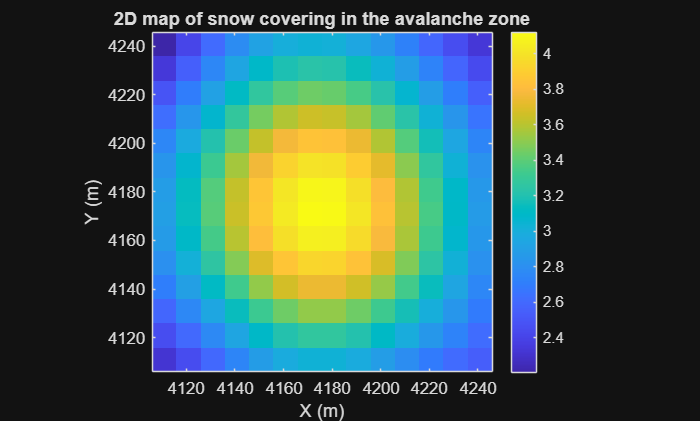

figure, clf;

imagesc(x(idx_x), y(idx_y), H)

set(gca, 'YDir', 'normal')

xlabel('X (m)')
ylabel('Y (m)')
title('2D map of snow covering in the avalanche zone')

colormap(parula)
colorbar
axis equal tight